Reproducing Figure 2 in the main text

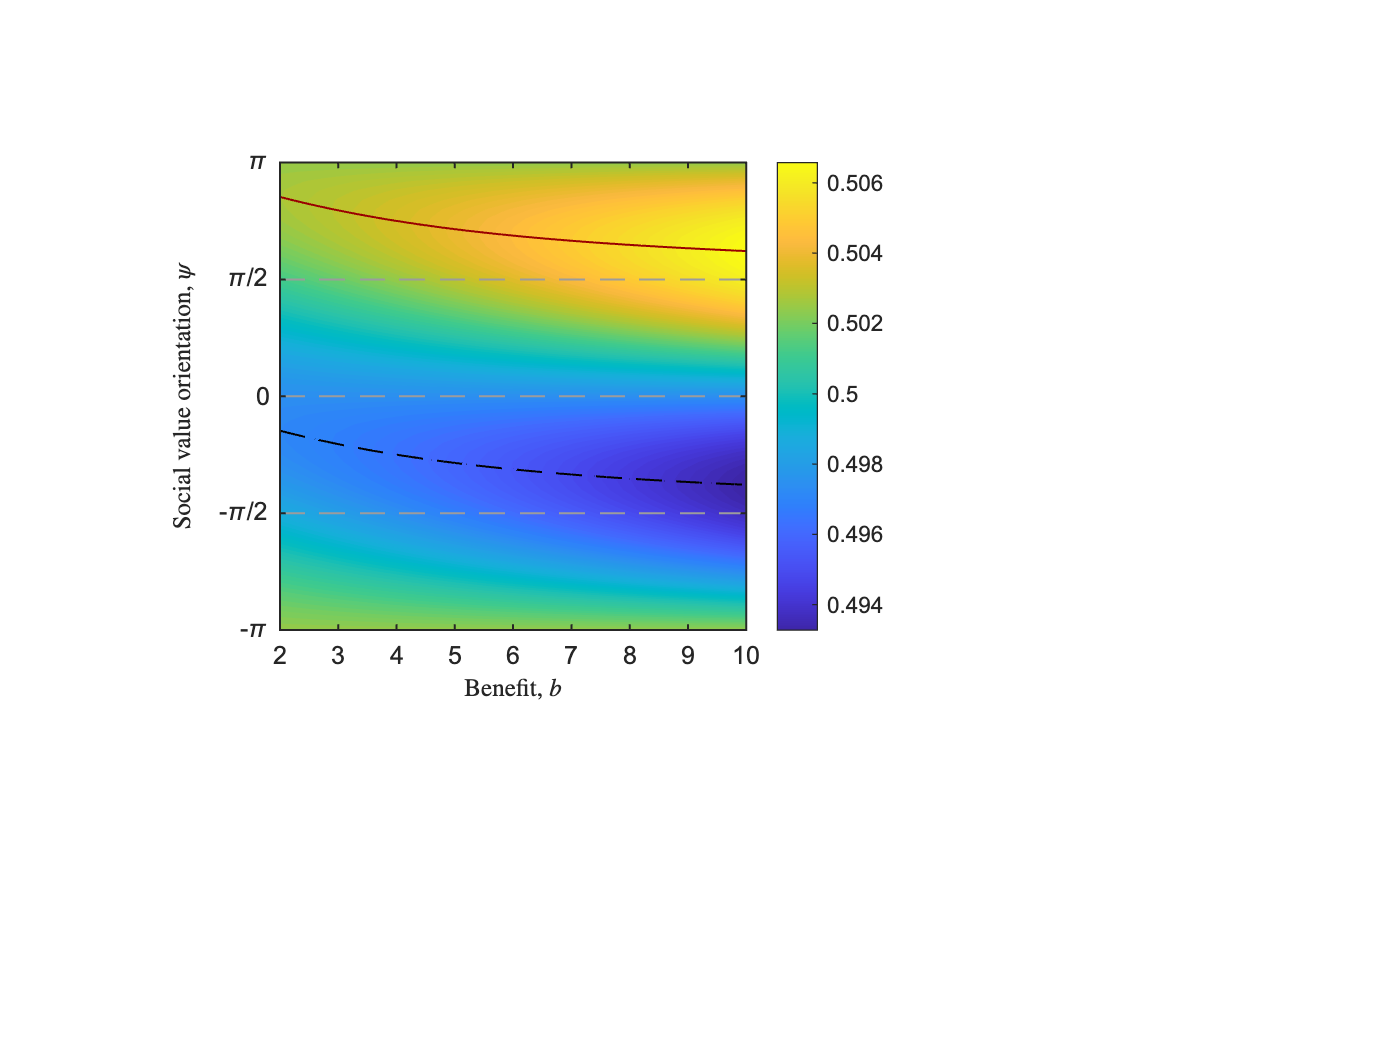

clear; close all;

color_list = [255 102 102;
              102 102 255;
              0 156 0;
              102 102 0;
              153 0 0;
              0 0 196;
              0 0 0;
              156 156 156;
              0 153 153;
              0 128 255;
              255 255 255]/255;
linewidth1 = 0.8;
linewidth2 = 0.8;
marksize = 8;
fontsize_scale = 10;
fontsize_variable = 10;

figure(1);

subplot(1,2,1)
pos = [0.20 0.40 0.42 0.445];
ax = subplot('Position',pos);

syms beta b c phi k;
x = 1/2+beta/4*(-c*cos(phi)+b/k*sin(phi));
xx = subs(x,[beta,c,k],[0.01,1,4]);

b_list = 2:0.2:10;
phi_list = -pi:pi/25:pi;
[X1,Y1] = meshgrid(b_list,phi_list);
xC_mat1 = zeros(length(b_list),length(phi_list));
for i = 1:length(b_list)
    for j = 1:length(phi_list)
        xC_mat1(i,j) = subs(xx,[b phi],[b_list(i) phi_list(j)]);
    end
end

[~,h] = contourf(X1,Y1,transpose(xC_mat1),0.493:0.014/100:0.507); hold on;
colormap(parula);
set(h,'LineColor','none');
colorbar();

psi_list1=pi+atan(-b_list/4);
psi_list2=atan(-b_list/4);
plot(b_list,psi_list1,'-','LineWidth',linewidth1,'Color',color_list(5,:)); 
plot(b_list,psi_list2,'--','LineWidth',linewidth1,'Color',color_list(7,:)); 

xlim = [2,10];
ylim = [-pi,pi];

plot(xlim,[pi/2 pi/2],'--','LineWidth',linewidth2,'Color',color_list(8,:)); 
plot(xlim,[0 0],'--','LineWidth',linewidth2,'Color',color_list(8,:)); 
plot(xlim,[-pi/2 -pi/2],'--','LineWidth',linewidth2,'Color',color_list(8,:)); 

set(ax,'Fontname','Arial','FontSize',fontsize_variable,'linewidth',linewidth2);
set(ax,'xlim',xlim);
set(ax,'XTick',2:1:10);
set(ax,'ylim',ylim);
set(ax,'YTick',-pi:pi/2:pi);
set(gca,'YTickLabel',{'-\pi','-\pi/2','0','\pi/2','\pi'},'FontSize',fontsize_variable,'Fontname', 'Arial');

xlabel('Benefit, $b$','interpreter','latex','FontSize',fontsize_variable,'Fontname', 'Arial');
ylabel('Social value orientation, $\psi$','interpreter','latex','FontSize',fontsize_variable,'Fontname', 'Arial');